% TAIL DESIGN
% AUTHOR : MONISHA VIJAYAN (AE25M037)
clear all
clc
X_cg=0.24106;
c_bar=0.2653;
X_ac_w=0.20193;
X_ac_f=0.1175;
Kn=0.10;
S=0.5307;
S_t=0.25*S;
eta=0.99;
AR=7.53;
CL_w=0.6;
CLalpha_t=3.8310;
CLalpha=4.5696;
e=0.7648;
Cmac_w=-0.0683;
Cmac_f=0;
CL_f =0.061015;
Cm_f=Cmac_f+CL_f*(X_cg-X_ac_f)/c_bar;
de_da=(2*CLalpha)/(pi*e*AR);
X_np=X_cg+(Kn*c_bar);
l_t=(((X_np-X_ac_w)+(Cm_f/CLalpha))*S)/(eta*S_t*(CLalpha_t/CLalpha)*(1-de_da));
alpha=3*pi/180;
func=@(it) Cmac_w + CL_w*(X_cg-X_ac_w) ...
           -eta*(S_t/S)*(CLalpha_t*(alpha+it-de_da*alpha))*(l_t/c_bar) ...
           +Cm_f;
it=fzero(func,-3*pi/180);
epsilon=de_da*alpha;
alpha_t=alpha+it-epsilon;
CL_t=CLalpha_t*alpha_t;
Cm_cg=Cmac_w+CL_w*(X_cg-X_ac_w)-eta*(S_t/S)*CL_t*(l_t/c_bar)+Cm_f;
l_t

l_t = 0.7000

it_deg=it*180/pi

it_deg = -1.8603

Cm_cg

Cm_cg = 0

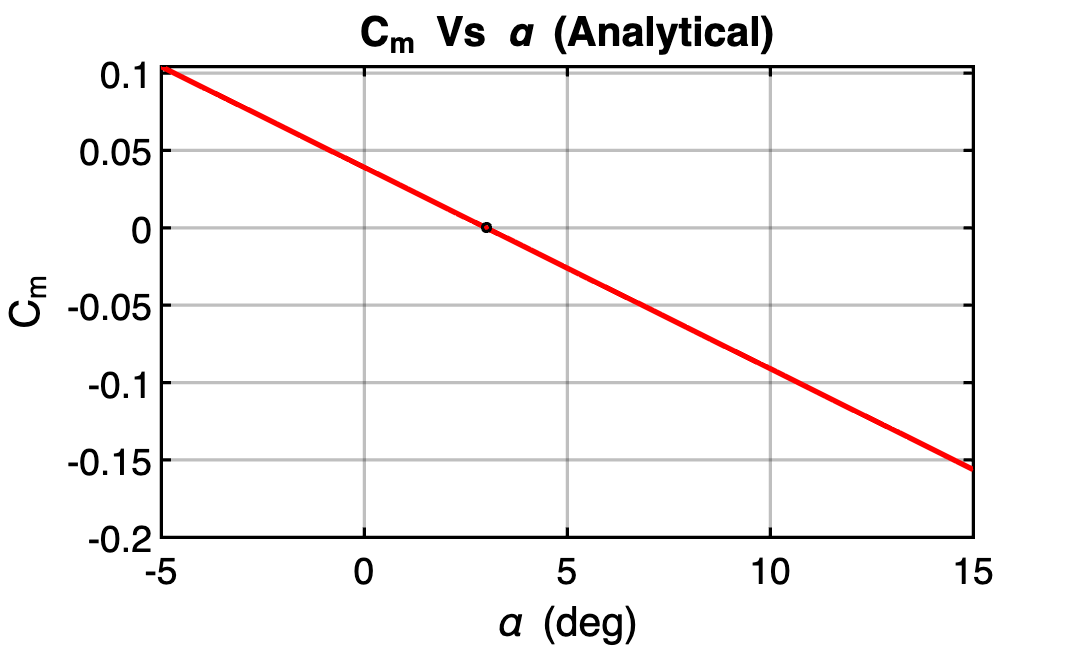


alpha0_w=-4*pi/180;
epsilon0=0;
de_da=(2*CLalpha)/(pi*e*AR);
Cm_alpha_f=-0.1817;
V_H=(S_t*l_t)/(S*c_bar);
Cm_alpha=((X_cg-X_ac_w)/c_bar)*CLalpha-eta*V_H*CLalpha_t*(1-de_da)+Cm_alpha_f;
alpha_trim=3*pi/180;
Cm0=-Cm_alpha*alpha_trim;
alpha=linspace(-5,15,100)*pi/180;
Cm=Cm0+Cm_alpha*alpha;
figure("Color",'white')
plot(alpha*180/pi,Cm,'LineWidth',2,'Color','r')
title('C_m Vs \alpha (Analytical)','Color','k')
xlabel('\alpha (deg)')
ylabel('C_m')
ax=gca;
ax.Color='w';         
ax.XColor='k';       
ax.YColor='k'; 
ax.GridColor='k';    
ax.MinorGridColor='k';
set(gca,'FontSize',14,'LineWidth',1.2)
hold on
plot(alpha_trim*180/pi,0,'ko','MarkerSize',3,'LineWidth',1.2)
grid on